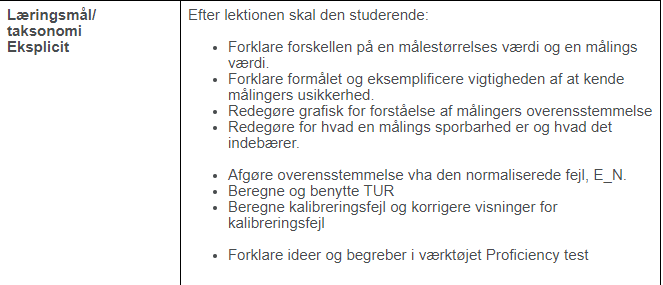

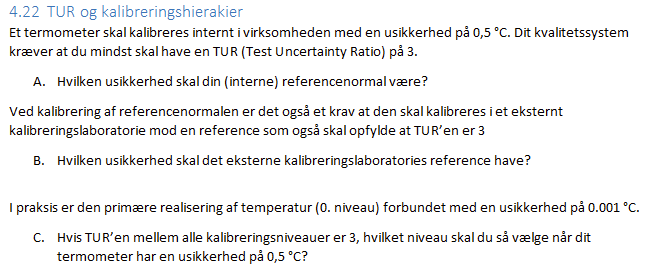

clc; clear all; format short;

% Opgave 4.22

% Opgave a)
dut = 0.5; % Den ønskede usikkerhed på virksomhedens termometer
TUR = 3;   % Test uncertainty ratio

REF = dut/TUR   % Den reference usikkerhed kalibrerings termometeret skal have

REF = 0.1667



% Opgave b)
dut_ref = REF;
TUR_ref = 3;

REF_ref = dut_ref/TUR_ref

REF_ref = 0.0556


% Opgave c)
dut_niveau = 0.5;
TUR_tot = 3;
REF = 0.001;



 
for i = 1:10
    
    REF = REF*TUR_tot;
    REFs(i) = REF;

end
REFs'

ans =     0.0030
    0.0090
    0.0270
    0.0810
    0.2430
    0.7290
    2.1870
    6.5610
   19.6830
   59.0490




% Opgave E
% Beskriv hvilken operationel forskel der er mellem et kalibreringshieraki 
% der har mange (f.eks. 6) og få (f.eks. 2) niveauer. Er der økonomisk forskel?

% Jo lavere niveau, jo flere kalibreringer skal der til for at opnå en
% mindre usikkerhed (mere præcis måling), desto dyrere vil det blive


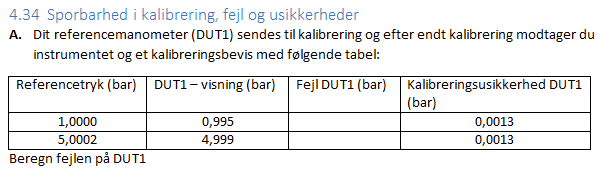

clc; clear all;

REF_tryk = [1, 5.0002]';
dut1 = [0.995, 4.999]';

% Det er altid DUT - REF

nn = dut1 - REF_tryk

nn =    -0.0050
   -0.0012


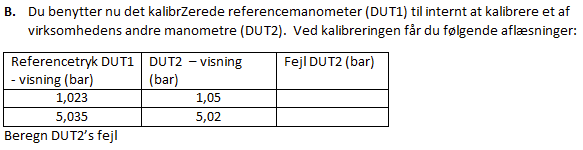

dut1 = [1.023, 5.035]'; % REF
dut2 = [1.05, 5.02]';   % DUT

fejl_dut2 = dut2 - dut1

fejl_dut2 =     0.0270
   -0.0150


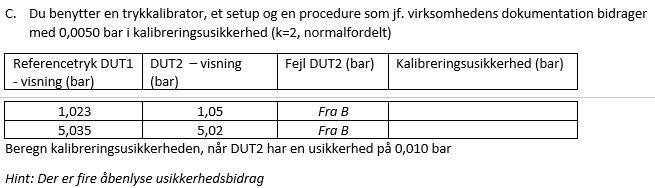

data = [dut1, dut2, fejl_dut2]

data =     1.0230    1.0500    0.0270
    5.0350    5.0200   -0.0150



dut2_kal_fejl = 0.01;
dut_bidrag = 0.005;

kal_usi = dut2_kal_fejl + dut_bidrag;



data_endelig = [dut1, dut2, fejl_dut2, [kal_usi;kal_usi]]

data_endelig =     1.0230    1.0500    0.0270    0.0150
    5.0350    5.0200   -0.0150    0.0150



disp(table(data_endelig))

               data_endelig            
    ___________________________________

    1.023      1.05     0.027     0.015
    5.035      5.02    -0.015     0.015

